# **Beam stresses and deflections (Beam-Column)**

[Beam stresses and deflections — PyMAPDL Examples](https://examples.mapdl.docs.pyansys.com/version/dev/verif-manual/vm-002-beam_stresses_and_deflections.html)

![](../utils/verify-beam.png)

clc; clear;

opsMAT = OpenSeesMatlab();
ops = opsMAT.opensees;

ops.wipe();
ops.model('basic', '-ndm', 2, '-ndf', 3);

%% -----------------------------
%  Geometry and material
%  Units: in, lb, psi
%% -----------------------------
E  = 30e6;          % psi
nu = 0.3;           % not used in 2D elasticBeamColumn
A  = 50.650;        % in^2
Iz = 7892.0;        % in^4  (major bending inertia)
c  = 15.0;          % in     (distance from neutral axis to extreme fiber)

L  = 120.0;         % each segment length, in
w  = 10000/12;      % lb/in

%% -----------------------------
%  Nodes
%% -----------------------------
ops.node(1,   0.0, 0.0);
ops.node(2, 120.0, 0.0);
ops.node(3, 240.0, 0.0);
ops.node(4, 360.0, 0.0);
ops.node(5, 480.0, 0.0);

%% -----------------------------
%  Boundary conditions
%  Same restraint intent as the reference example
%% -----------------------------
ops.fix(2, 1, 1, 0);   % UX, UY fixed
ops.fix(4, 0, 1, 0);   % UY fixed

%% -----------------------------
%  Transformation and elements
%% -----------------------------
ops.geomTransf('Linear', 1);

ops.element('elasticBeamColumn', 1, 1, 2, A, E, Iz, 1);
ops.element('elasticBeamColumn', 2, 2, 3, A, E, Iz, 1);
ops.element('elasticBeamColumn', 3, 3, 4, A, E, Iz, 1);
ops.element('elasticBeamColumn', 4, 4, 5, A, E, Iz, 1);

%% -----------------------------
%  Loads: distributed loads on the two overhangs
%% -----------------------------
ops.timeSeries('Linear', 1);
ops.pattern('Plain', 1, 1);

% 2D beamUniform: Wy along local y
% downward load => negative
ops.eleLoad('-ele', 1, '-type', '-beamUniform', -w);
ops.eleLoad('-ele', 4, '-type', '-beamUniform', -w);

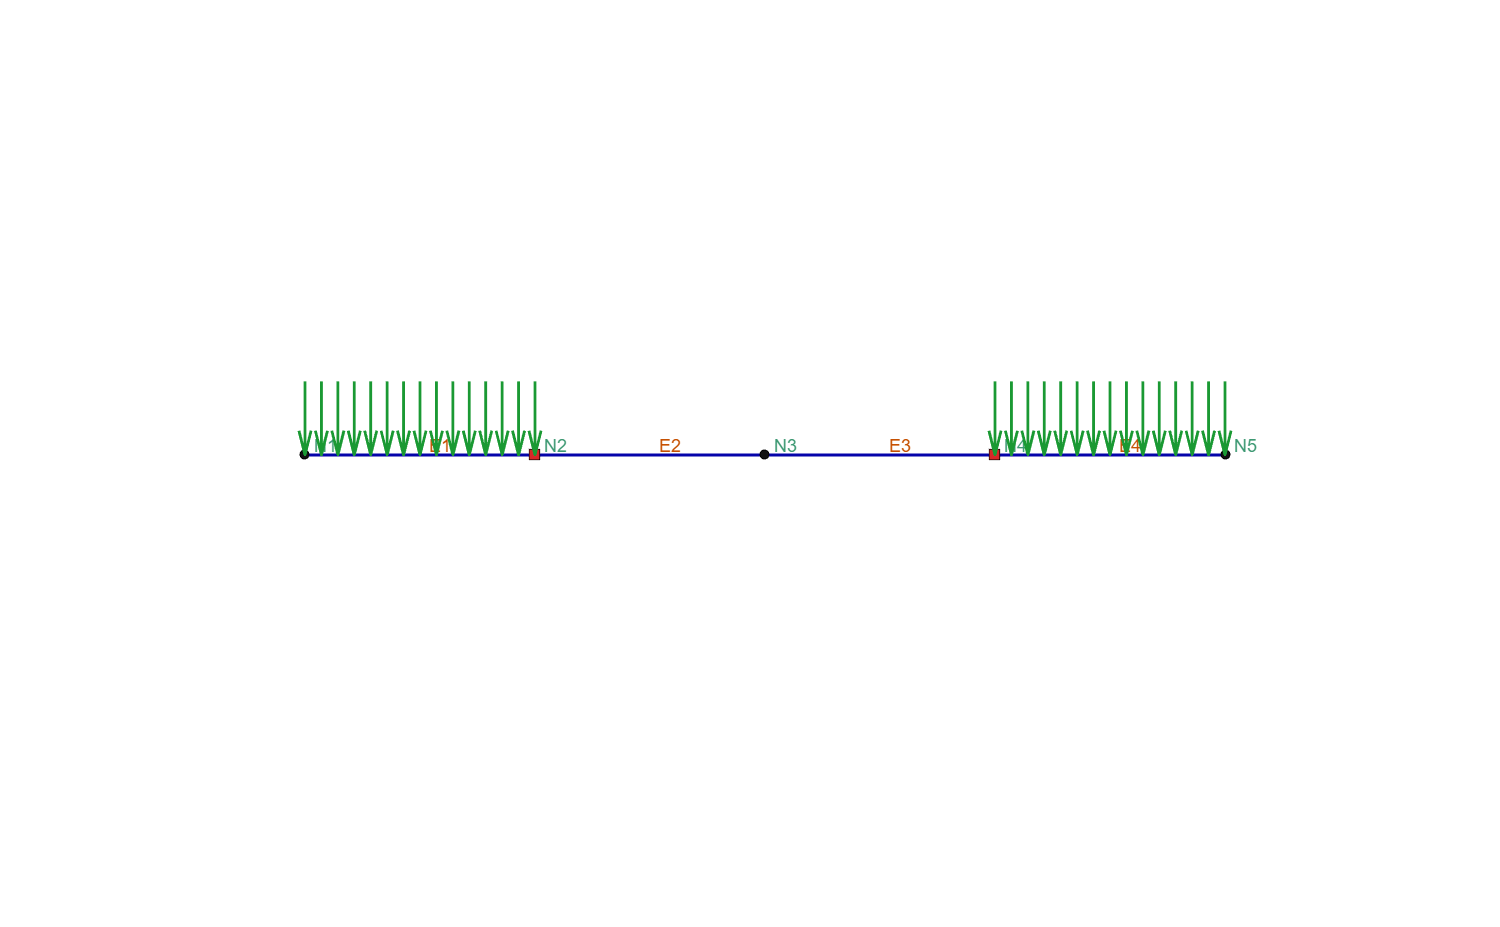

opts = opsMAT.vis.defaultPlotModelOptions;
opts.nodes.showLabels = true;
opts.elements.showLabels = true;
opts.loads.showElement = true;


opsMAT.vis.plotModel(opts=opts);
ylim([0 1])
axis off

Nsteps = 2;
ops.constraints('Plain');
ops.numberer('RCM');
ops.system('BandGeneral');
ops.test('NormDispIncr', 1.0e-12, 50);
ops.algorithm('Newton');
ops.integrator('LoadControl', 1.0 / Nsteps);
ops.analysis('Static');

ODB = opsMAT.post.createODB("myODB", interpolateBeamDisp=6);  % create ODB, 6 points in interpolateBeamDisp
for i = 1:Nsteps
    ok = ops.analyze(1);
    ODB.fetchResponseStep();
end
ODB.saveResponse();

[OpenSeesMatlab] odbTag=myODB saved → .openseesmatlab.output\Responses-myODB.odb


nodeResp = opsMAT.post.getNodalResponse("myODB");

nodeTags = nodeResp.nodeTags;
idx = nodeTags == 3;
dispN3 = nodeResp.disp.uy(:, idx);  % nsteps * 1
uy_mid = max(dispN3(:));

deflection_target = 0.182;     % in
deflection_ratio = abs(uy_mid) / deflection_target;

fprintf('Deflection (in)     %12.6f %20.6f %12.6f\n', deflection_target, uy_mid, deflection_ratio);

Deflection (in)         0.182000             0.182463     1.002545


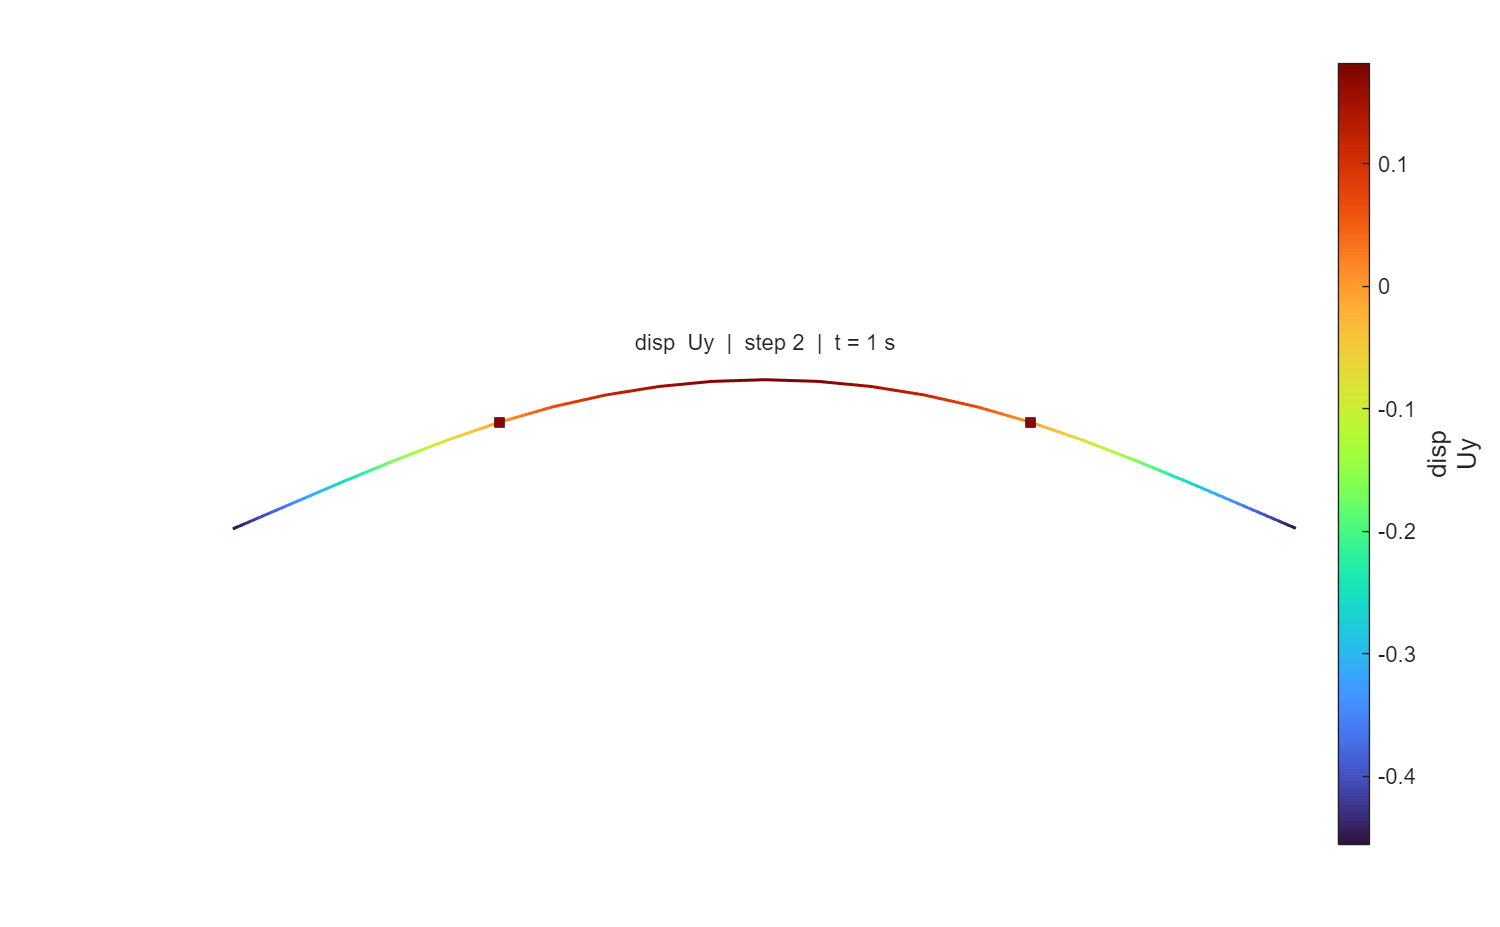



opsMAT.vis.plotNodalResponse(nodeResp, respType="disp", stepIdx="absMax", respComponent="Uy");
axis off

frameResp = opsMAT.post.getElementResponse("myODB", eleType="Frame");

eleTags = frameResp.eleTags;
idxE2 = eleTags == 2;

secFo = frameResp.sectionForces.Mz(:, idxE2, end);  % last section, ele-2
M_mid = max(abs(secFo(:)));
sigma_max = M_mid * c / Iz;

stress_target     = 11400.0;   % psi
stress_ratio     = sigma_max / stress_target;

fprintf('Stress (psi)        %12.6f %20.6f %12.6f\n', ...
    stress_target, sigma_max, stress_ratio);

Stress (psi)        11400.000000         11403.953371     1.000347


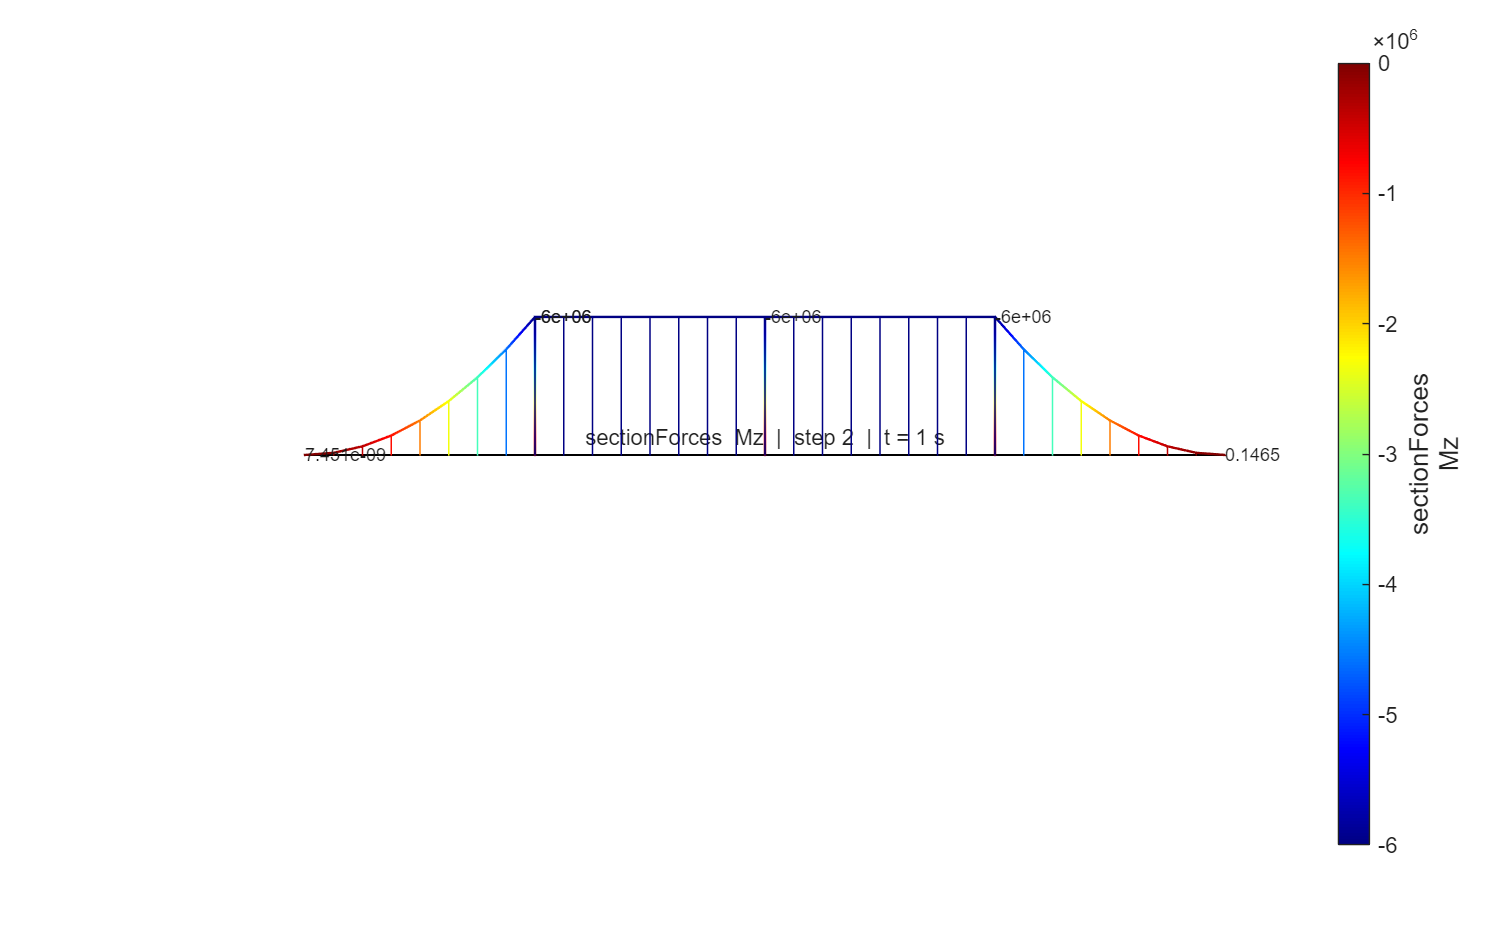

opts = opsMAT.vis.defaultPlotFrameResponseOptions;
opts.style = "wireframe";

opsMAT.vis.plotFrameResponse(frameResp, ...
    stepIdx="absMax", respType="sectionForces", respComponent="Mz",...
    opts=opts);
ylim([0, 1])
axis off